Zadanie 1:

a) wyznaczenie charakterystyki za pomocą funkcji nyquist:

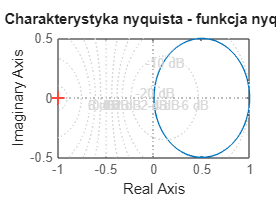

%Dane
A = 1;
B = 1;

s = tf('s');
G = A/(B*s + 1);

%G = tf([A],[B,1]);
figure;
nyquist(G);
title('Charakterystyka nyquista - funkcja nyquist');
grid on;

b) "ręczne" wyliczanie charakterystyki

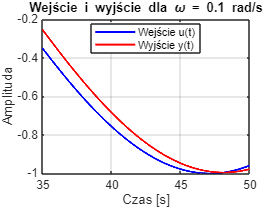

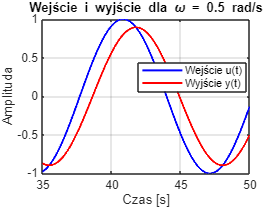

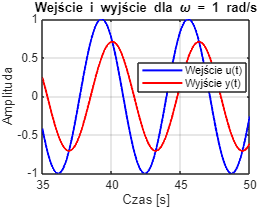

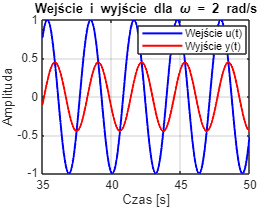

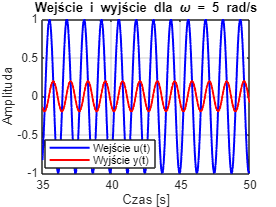

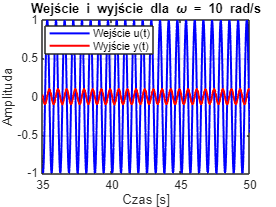

% Dane 
A = 1;
B = 1;

omega_values = [0.1, 0.5, 1, 2, 5, 10]; % Wybrane częstotliwości
t = 0:0.01:50; % Wektor czasu

% Inicjalizacja tablic na wyniki
A_results = zeros(size(omega_values));
phi_results = zeros(size(omega_values));

colors = lines(length(omega_values)); % Automatyczne kolory dla różnych omega

% --- Pętla dla każdej omega ---
for i = 1:length(omega_values)
    omega = omega_values(i);
    u = sin(omega*t); % Sygnał wejściowy
    
    % Symulacja odpowiedzi układu
    y = lsim(G, u, t);
    
    % Pominięcie części przejściowej (tylko stan ustalony)
    steady_state_start = floor(length(t)*0.7);
    t_steady = t(steady_state_start:end);
    u_steady = u(steady_state_start:end);
    y_steady = y(steady_state_start:end);
    
    % Dopasowanie sinusoidy do odpowiedzi ustalonej
    X = [sin(omega*t_steady)' cos(omega*t_steady)'];
    coeffs = X \ y_steady;
    a = coeffs(1);
    b = coeffs(2);
    
    % Obliczenie amplitudy i fazy
    A_est = sqrt(a^2 + b^2);
    phi_est = atan2(b, a);
    
    % Zapisanie wyników
    A_results(i) = A_est;
    phi_results(i) = phi_est;
    
    % --- WYKRES: Wejście i wyjście na jednym wykresie ---
    figure;
    plot(t_steady, u_steady, 'b-', 'LineWidth', 1.5);
    hold on;
    plot(t_steady, y_steady, 'r-', 'LineWidth', 1.5);
    xlabel('Czas [s]');
    ylabel('Amplituda');
    title(['Wejście i wyjście dla \omega = ', num2str(omega), ' rad/s']);
    legend('Wejście u(t)', 'Wyjście y(t)', 'Location', 'best');
    grid on;
end

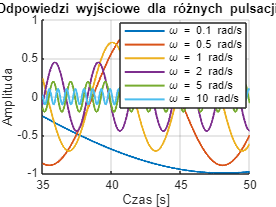


% --- WSPÓLNY WYKRES wszystkich wyjść y(t) ---
figure;
hold on;
legend_entries = {};

for i = 1:length(omega_values)
    omega = omega_values(i);
    u = sin(omega*t);
    y = lsim(G, u, t);
    
    steady_state_start = floor(length(t)*0.7);
    t_steady = t(steady_state_start:end);
    y_steady = y(steady_state_start:end);
    
    plot(t_steady, y_steady, 'Color', colors(i,:), 'LineWidth', 1.5);
    legend_entries{end+1} = ['\omega = ', num2str(omega), ' rad/s'];
end

xlabel('Czas [s]');
ylabel('Amplituda');
title('Odpowiedzi wyjściowe dla różnych pulsacji \omega');
legend(legend_entries, 'Location', 'best');
grid on;

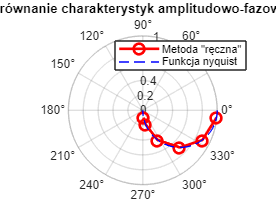


% --- Charakterystyka amplitudowo-fazowa ---
figure;
polarplot(phi_results, A_results, 'ro-', 'LineWidth', 2, 'MarkerSize', 8);
hold on;

% Dodanie charakterystyki Nyquista dla porównania
[re, im] = nyquist(G);
polarplot(squeeze(atan2(im, re)), squeeze(sqrt(re.^2 + im.^2)), 'b--');
legend('Metoda "ręczna"', 'Funkcja nyquist', 'Location', 'best');
title('Porównanie charakterystyk amplitudowo-fazowych');
grid on;


% --- Tabela wyników ---
fprintf('omega\tAmplituda\tFaza [rad]\tFaza [deg]\n');

omega	Amplituda	Faza [rad]	Faza [deg]


for i = 1:length(omega_values)
    fprintf('%.1f\t%.4f\t\t%.4f\t\t%.2f\n', omega_values(i), A_results(i), ...
            phi_results(i), rad2deg(phi_results(i)));
end

0.1	0.9950		-0.0997		-5.71
0.5	0.8944		-0.4636		-26.57
1.0	0.7071		-0.7854		-45.00
2.0	0.4472		-1.1071		-63.43
5.0	0.1961		-1.3734		-78.69
10.0	0.0994		-1.4711		-84.29
